clc
clear
% This compares the Xsens .c3d output with OMC data.
for i = 1:4
    i
    switch i
        case 1
            XsensC3dFileName = 'Data\XsensData\Subject1\HipF1\xsensHipF1.c3d';
            XsensXlsFileName = 'Data\XsensData\Subject1\HipF1\xsensHipF1.xlsx';
            OMCC3dFileName = 'Data\XsensData\Subject1\HipF1\OMCHipF1.c3d';
            XsensSampleRate = 240;
        case 2
            XsensC3dFileName = 'Data\XsensData\Subject1\HipF2\xsensHipF2.c3d';
            XsensXlsFileName = 'Data\XsensData\Subject1\HipF2\xsensHipF2.xlsx';
            OMCC3dFileName = 'Data\XsensData\Subject1\HipF2\OMCHipF2.c3d';
            XsensSampleRate = 240;
        case 3
            XsensC3dFileName = 'Data\XsensData\Subject2\HipF1\xsensHipF1.c3d';
            XsensXlsFileName = 'Data\XsensData\Subject2\HipF1\xsensHipF1.xlsx';
            OMCC3dFileName = 'Data\XsensData\Subject2\HipF1\OMCHipF1.c3d';
            XsensSampleRate = 120;
        case 4
            XsensC3dFileName = 'Data\XsensData\Subject2\HipF2\xsensHipF2.c3d';
            XsensXlsFileName = 'Data\XsensData\Subject2\HipF2\xsensHipF2.xlsx';
            OMCC3dFileName = 'Data\XsensData\Subject2\HipF2\OMCHipF2.c3d';
            XsensSampleRate = 120;
    end

    imcData = Data;
    omcData = Data;
    acq = btkReadAcquisition(XsensC3dFileName);
    xsensMarkers = btkGetMarkers(acq);
    segPos = readtable(XsensXlsFileName,"Sheet","Segment Position");
    imcData.getXsensLandmarks(xsensMarkers)
    imcData.RHipCenter = roundn(segPos{:,["RightUpperLegX","RightUpperLegY","RightUpperLegZ"]}.*1000,-1);
    imcData.xsensResample(XsensSampleRate);
%     imcData.setHipAsOrigin;
    imcData.setHipAsOriginXsens;
    imcData.rotateReferenceFrame(eul2rotm([pi,0,0]));
    acq = btkReadAcquisition(OMCC3dFileName);
    omcMarkers = btkGetMarkers(acq);
    omcData.getOMCLandmarks(omcMarkers);
    omcData.setHipAsOrigin;
    switch i
        case 1
            save('Data\XsensData\Subject1\HipF1\rawData.mat',"imcData","omcData")
        case 2
            save('Data\XsensData\Subject1\HipF2\rawData.mat',"imcData","omcData")
        case 3
            save('Data\XsensData\Subject2\HipF1\rawData.mat',"imcData","omcData")
        case 4
            save('Data\XsensData\Subject2\HipF2\rawData.mat',"imcData","omcData")
    end

end

i = 1

i = 2

i = 3

i = 4

i = 1

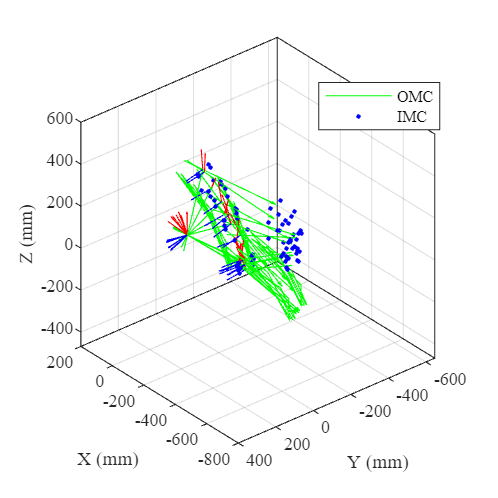

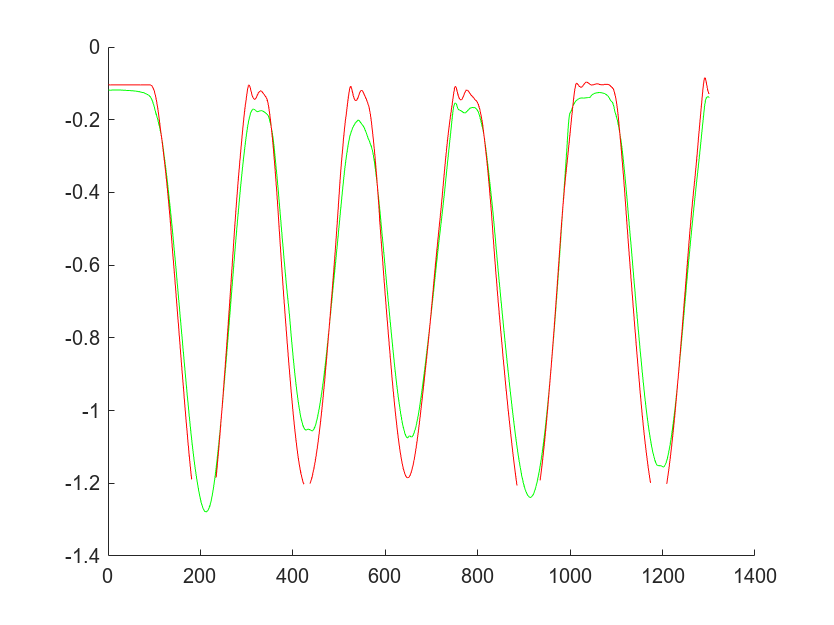

ROMF = 99.2241

ROMT = 93.9868

i = 2

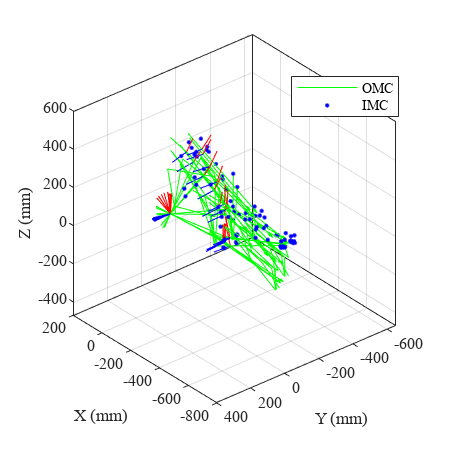

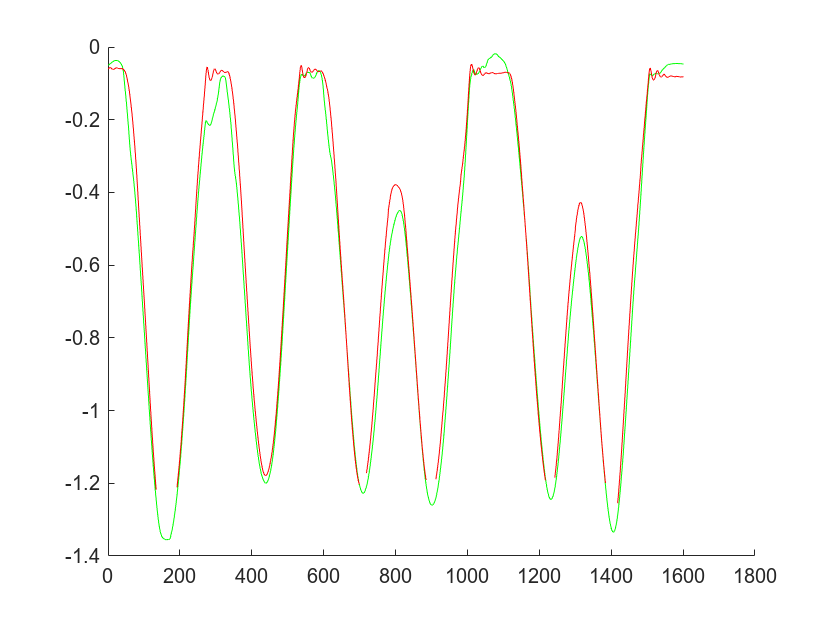

ROMF = 114.6418

ROMT = 114.8317

i = 3

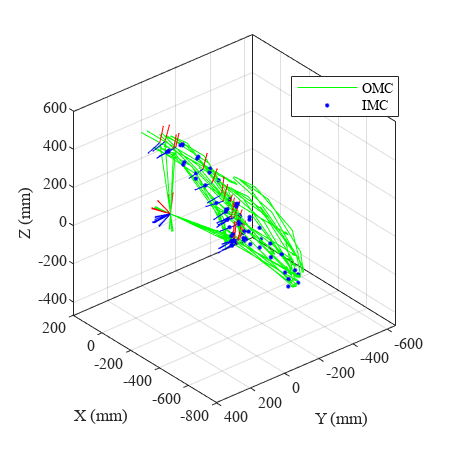

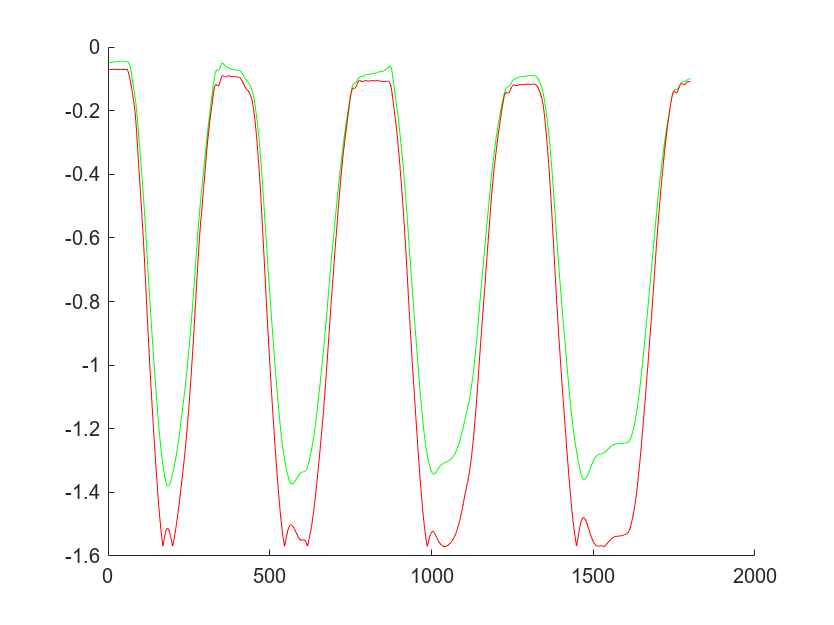

ROMF = 102.0753

ROMT = 95.1269

i = 4

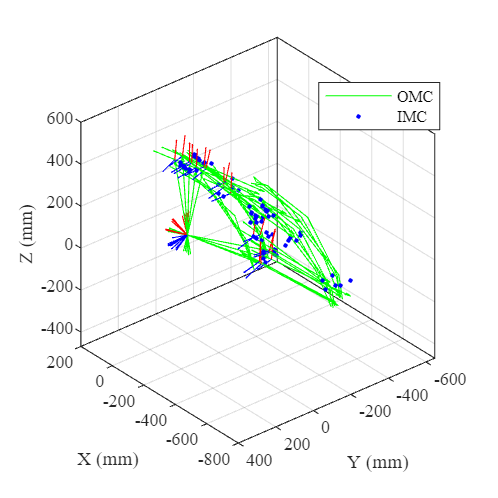

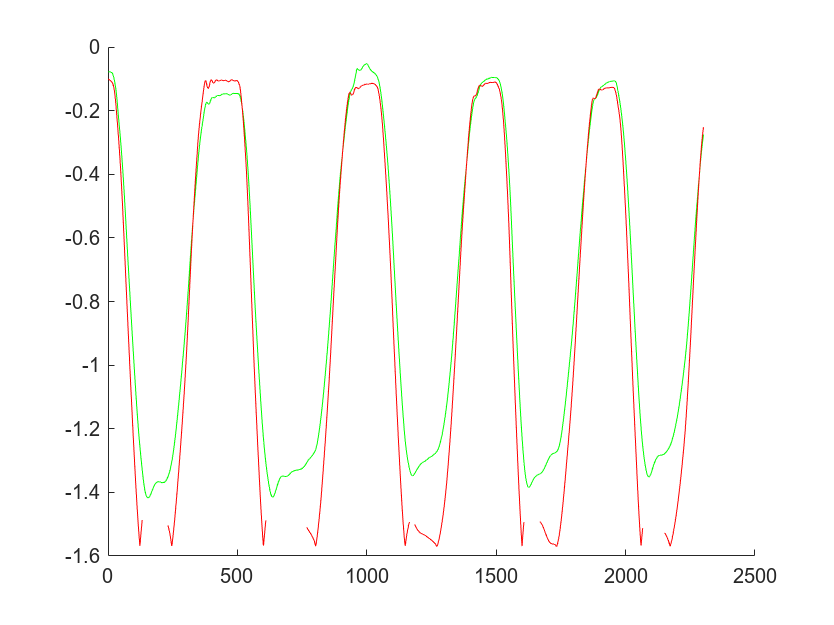

ROMF = 101.4610

ROMT = 93.4459

clc
clear
warning('off')
for i = 1:4
    i
    switch i
        case 1
            load('Data\XsensData\Subject1\HipF1\rawData.mat')
            %   Manually select data to caluclate.
            omcData.selectRange(146,1446)
            imcData.selectRange(100,1400)
            %   Manually select the highest and lowest positions of the
            %   knee joint center to unify the global reference frame.
            top = 648;
            bottom = 1028;
            imcData.rotateReferenceFrame(eul2rotm([-pi/2,0,0]))
            omcData.rotateReferenceFrame(eul2rotm([pi,0,0]))
        case 2
            load('Data\XsensData\Subject1\HipF2\rawData.mat')
            %             figure
            %             plot(omcData.REFM(:,3),'b')
            omcData.selectRange(436,2036)
            imcData.selectRange(400,2000)
            top = 537;
            bottom = 1121;
            omcData.rotateReferenceFrame(eul2rotm([pi,0,0]))
        case 3
            load('Data\XsensData\Subject2\HipF1\rawData.mat')
            omcData.selectRange(102,1902)
            imcData.selectRange(100,1900)
            top = 572;
            bottom = 1264;
            omcData.rotateReferenceFrame(eul2rotm([pi,0,pi/2]))
        case 4
            load('Data\XsensData\Subject2\HipF2\rawData.mat')
            omcData.selectRange(107,2407)
            imcData.selectRange(100,2400)
            top = 1200;
            bottom = 323;
            imcData.rotateReferenceFrame(eul2rotm([pi/2,0,0]))
            omcData.rotateReferenceFrame(eul2rotm([pi,0,pi/2]))
    end

% 
%     to = 0.01:0.01:size(omcData.REFM)/100;
%     ti = 0.01:0.01:size(imcData.REFM)/100;
%     figure
%     hold on
%     plot(to,omcData.REFM(:,3),'b')
%     plot(ti,imcData.REFM(:,3),'g')
%     TFo = islocalmax(omcData.REFM(:,3),'MinSeparation',100);
%     plot(to(TFo),omcData.REFM(TFo,3),'*')
%     TFi = islocalmax(imcData.REFM(:,3),'MinSeparation',100);
%     plot(ti(TFi),imcData.REFM(TFi,3),'*')


    omcData.getFemoralOrientation;
    omcData.getTibiaCluster
    [~,window] = omcData.getAoRCalculationWindow;
    omcData.getKneeAoR_F(window,2, 1);
    sd = omcData.SDRKneeAoR_F;
    KneeAoRSD(i,1) = sd;
    omcData.getTibiaOrientation;


    imcData.getFemoralOrientation;
    imcData.getTibiaCluster
    [calculationFlag,window] = imcData.getAoRCalculationWindow;
    imcData.getKneeAoR_F(window,1, 1);
    imcData.getTibiaOrientation;

    p = Ploter('');
    p.plotInit

    % Just for legend
    p1 = plot(-1000,0,'g');
    p2 = plot(-1000,0,'b.');
    legend("Position", [0.64285,0.74145,0.23731,0.089956])

    % p.plotMarkerTrajectories(imcData,'b-',1,50,1000)
    p.plotMarkerTrajectories(omcData,'g',1,50,1000)
    %     p.plotFemoralFrame(omcData,1,50,1000)
    %     p.plotFemoralFrame(imcData,1,50,1000)

    imcData.getFrameForUnifyByPeakPoint(bottom,top)
    omcData.getFrameForUnifyByPeakPoint(bottom,top)

    % p.plotFrame([0,0,0],omcData.ReferenceFrameInit,200)
    RotationInit = omcData.frameForUnify/imcData.frameForUnify;
    imcData.rotateReferenceFrame(RotationInit)

    p.plotMarkerTrajectories(imcData,'b.',1,50,1000)

    p.plotFemoralFrame(imcData,1,200,1000)
    p.plotFemoralFrame(omcData,1,200,1000)

    p.plotTibiaFrame(imcData,1,100,1000)
    p.plotTibiaFrame(omcData,1,100,1000)
    legend([p1,p2],{'OMC','IMC'})

    figure
    hold on
    imcSegAng = atan(imcData.REFM(:,3)./imcData.REFM(:,1));
    imcSegAng(any(imcSegAng>0)) = -imcSegAng(any(imcSegAng>0));
    plot(imcSegAng,'g')
% 
    omcSegAng = atan(omcData.REFM(:,3)./omcData.REFM(:,1));
    omcSegAng(any(omcSegAng>0,2),:) = -omcSegAng(any(omcSegAng>0,2),:);
    plot(omcSegAng,'r')
%     SegHipError = imcSegAng-omcSegAng;
%     SegHipError(any(isnan(SegHipError), 2),:) = [];
   
%     segHipRMSE = rms(SegHipError)./pi*180
%     segHipMeanError = mean(SegHipError)./pi*180
%     segHipMeanSD = std(SegHipError)./pi*180

    imcData.rotateReferenceFrame(eul2rotm([pi/2,0,pi/2]))
    omcData.rotateReferenceFrame(eul2rotm([pi/2,0,pi/2]))

    omcData.getEul;
    imcData.getEul;

    % to = 0.01:0.01:size(omcData.REFM)/100;
    % ti = 0.01:0.01:size(imcData.REFM)/100;
    % figure
    % hold on
    % plot(to,omcData.REFM(:,3),'b')
    % plot(ti,imcData.REFM(:,3),'g')
    % TFo = islocalmax(omcData.REFM(:,3),'MinSeparation',100);
    % plot(to(TFo),omcData.REFM(TFo,3),'*')
    % TFi = islocalmax(imcData.REFM(:,3),'MinSeparation',100);
    % plot(ti(TFi),imcData.REFM(TFi,3),'*')


%     t = 0.01:0.01:size(omcData.REFM)/100;
%     figure
%     subplot(2,2,1)
%     hold on;box on;grid on;title('REFM')
%     ylabel('position(mm)')
%     plot(t,omcData.REFM(:,1),'r')
%     plot(t,omcData.REFM(:,2),'g')
%     plot(t,omcData.REFM(:,3),'b')
%     plot(t,imcData.REFM(:,1),'r--')
%     plot(t,imcData.REFM(:,2),'g--')
%     plot(t,imcData.REFM(:,3),'b--')
%     subplot(2,2,2)
%     hold on;box on;grid on;title('REFL')
%     plot(t,omcData.REFL(:,1),'r')
%     plot(t,omcData.REFL(:,2),'g')
%     plot(t,omcData.REFL(:,3),'b')
%     plot(t,imcData.REFL(:,1),'r--')
%     plot(t,imcData.REFL(:,2),'g--')
%     plot(t,imcData.REFL(:,3),'b--')
%     legend({'OMC X','OMC Y','OMC Z','IMC X','IMC X','IMC X',})
%     subplot(2,2,3)
%     hold on;box on;grid on;title('RMM')
%     ylabel('position(mm)');xlabel('time(s)')
%     plot(t,omcData.RMM(:,1),'r')
%     plot(t,omcData.RMM(:,2),'g')
%     plot(t,omcData.RMM(:,3),'b')
%     plot(t,imcData.RMM(:,1),'r--')
%     plot(t,imcData.RMM(:,2),'g--')
%     plot(t,imcData.RMM(:,3),'b--')
%     subplot(2,2,4)
%     hold on;box on;grid on;title('RLM')
%     xlabel('time(s)')
%     plot(t,omcData.RLM(:,1),'r')
%     plot(t,omcData.RLM(:,2),'g')
%     plot(t,omcData.RLM(:,3),'b')
%     plot(t,imcData.RLM(:,1),'r--')
%     plot(t,imcData.RLM(:,2),'g--')
%     plot(t,imcData.RLM(:,3),'b--')

    error = Error(imcData,omcData);
    RMS(i,:) = error.RMS;

%     figure
%     hold on
%     plot(to,omcData.REFM(:,3),'b')
%     plot(ti,imcData.REFM(:,3),'g')


%     figure
%     subplot(1,2,1)
%     hold on;box on;grid on;title('Upper Leg Euler   ')
%     plot(omcData.RFemoralEul(:,1),'r')
%     plot(omcData.RFemoralEul(:,2),'g')
%     plot(omcData.RFemoralEul(:,3),'b')
%     plot(imcData.RFemoralEul(:,1),'r--')
%     plot(imcData.RFemoralEul(:,2),'g--')
%     plot(imcData.RFemoralEul(:,3),'b--')
% 
%     subplot(1,2,2)
%     hold on;box on;grid on;title('Lower Leg Euler   ')
%     plot(omcData.RTibiaEul(:,1),'r')
%     plot(omcData.RTibiaEul(:,2),'g')
%     plot(omcData.RTibiaEul(:,3),'b')
%     plot(imcData.RTibiaEul(:,1),'r--')
%     plot(imcData.RTibiaEul(:,2),'g--')
%     plot(imcData.RTibiaEul(:,3),'b--')

    error.getAngleRMS(omcData,imcData)
    RMSEul(i,:) =[error.rmsFemoralAngle, error.rmsTibiaAngle];

    error.getYAxisAngleRMS(omcData,imcData)
    yAxisRMSEul(i,:) =[error.rmsFemoralYAxis, error.rmsTibiaYAxis];

    max(imcData.REFM(3));
    topFrame = find(imcData.REFM(:,3)==max(imcData.REFM(:,3)));
    a = [0,0,-1];
    b = imcData.RFemoralRotm{topFrame(1),1}(:,2);
    ROMF = 180-acos(dot(a,b)/(norm(a)*norm(b)))./pi*180
    a = [0,0,-1];
    b = imcData.RTibiaRotm{topFrame(1),1}(:,2);
    ROMT = acos(dot(a,b)/(norm(a)*norm(b)))./pi*180

    RMSEulPercent(i,:) =[error.rmsFemoralAngle(1)./ROMF, error.rmsTibiaAngle(1)./ROMT];
    yAxisRMSEulPercent(i,:) =[error.rmsFemoralYAxis./ROMF, error.rmsTibiaYAxis./ROMT];


end


RMSTable = array2table(RMS);
RMSTable.Properties.VariableNames = {'REFM','REFL','RMM','RLM'}

RMSTable = 4×4 table
     REFM      REFL      RMM       RLM  
    ______    ______    ______    ______

    46.548    62.362    248.75    267.72
    43.923    61.364    126.73     145.1
        78    56.457    136.15    119.17
    86.299    69.465    145.33    133.18


RMSEulTable = array2table(RMSEul);
RMSEulTable.Properties.VariableNames = {...
    'R UpperLeg Z','R UpperLeg Y','R UpperLeg X',...
    'R LowerLeg Z','R LowerLeg Y','R LowerLeg X'}

RMSEulTable = 4×6 table
    R UpperLeg Z    R UpperLeg Y    R UpperLeg X    R LowerLeg Z    R LowerLeg Y    R LowerLeg X
    ____________    ____________    ____________    ____________    ____________    ____________

        4.535          17.031          12.127          36.645           5.731          3.0592   
       4.1544          5.6965          5.8803          17.179          7.8971          2.1234   
       11.074          9.8028          13.794          5.7728          6.3644          12.747   
       12.202          13.624          14.608          3.0663          9.5575          12.941   



 yAxisRMSEul

yAxisRMSEul =     4.8661   36.1538
    5.5947   17.1905
    8.8573   13.5468
   10.1514   13.4635



 mean(RMSEulPercent(2:4,:)).*100

ans =     8.8330    8.1032



 yAxisRMSEulPercent.*100

ans =     4.9042   38.4669
    4.8801   14.9702
    8.6773   14.2407
   10.0052   14.4078
